# Chapter 3, Section 2 (Part 2)

The goal of this activity is to introduce what is known as the **Span **of a set of vectors. Let's begin with the definition.

**Definition: ** Let $V$ be a vector space and let $S=\left\{\vec v_1,\ldots,\vec v_n\right\}$ be a (finite) subset of $V$. The **span** of $S$, denoted by $\text{span}(S)$, is the set


$$\text{span}(S)=\left\{c_1\vec v_1+\cdots+c_n\vec v_n: \ c_1,\ldots,c_n\in R\right\}$$


That is, $\text{span}(S)$ is the collection of all linear combinations of the vectors in $S=\left\{\vec v_1,\ldots,\vec v_n\right\}$.

# Example #1

Let $V=R^2$. Let $S=\left\{\pmatrix{3\cr 2}\right\}$. What is the $\text{span}(S)$?

**Solution: **We can simply describe the $\text{span}(S)=\left\{c\pmatrix{3\cr 2};\ c\in R\right\}$. But what does it look like? It's a line passing through the origin, because any multiple of $(3,2)^T$ will lie on this line. 

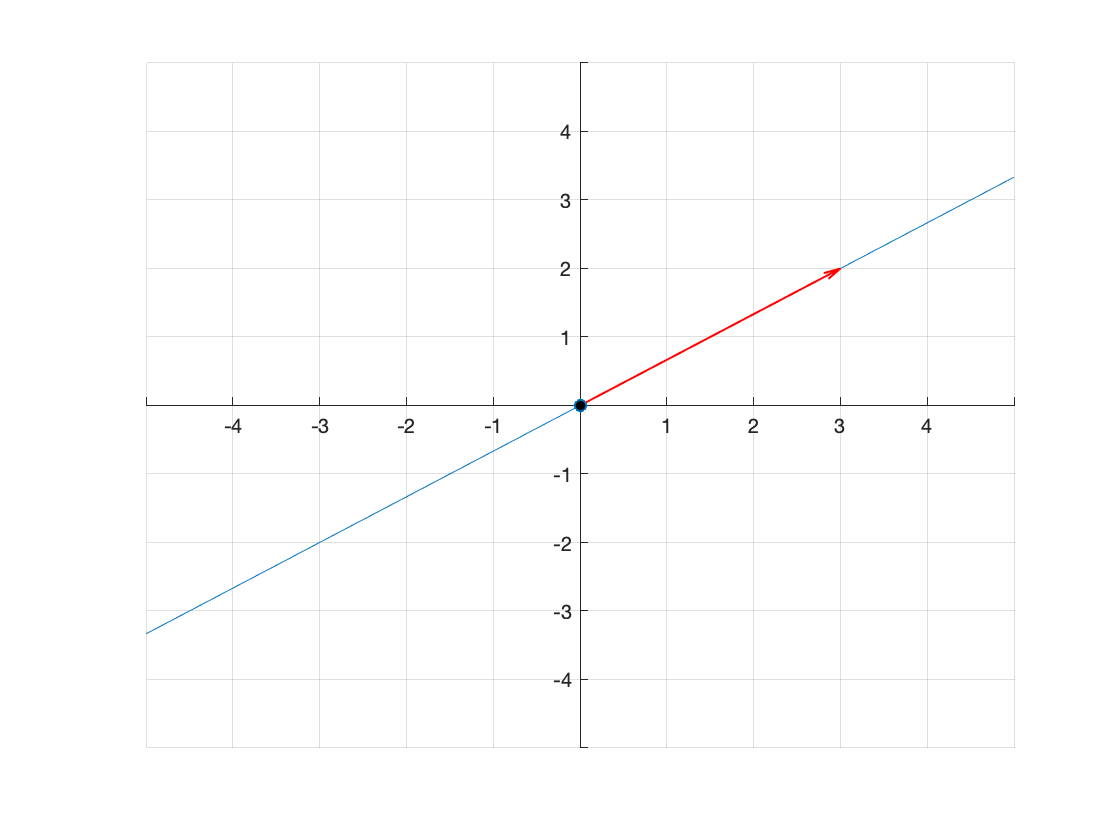

figure
line([-5,5],[-10/3,10/3])
hold on
quiver(0,0,3,2,0,'LineWidth',1,'Color','r')
plot(0,0,'o','MarkerFaceColor','k')
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
grid on
axis([-5,5,-5,5])
hold off

Note that the slope of the line is 2/3 and the $y$-intercept is 0, so if we use $y=mx+b$, the equation is $y=(2/3)x$. So each point on the line satisfies


$$\pmatrix{x\cr y}=\pmatrix{x\cr (2/3)x}=\frac13x\pmatrix{3\cr 2}$$


Because $x$ is an arbitrary real number, let's replace $(1/3)x$ with $c$, which tells us that all points on the line are defined by $c\pmatrix{3\cr 2}$. Thus, the line $y=(2/3)x$ is the $\text{span}(S)$.

# Example #2

Let $V=R^3$.  Let $S=\left\{\pmatrix{1\cr 1\cr 2},\ \pmatrix{-1\cr 1 \cr 2}\right\}$. What is the $\text{span}(S)$?

**Solution: **Algebraically, we can describe the $\text{span}(S)$ by taking all linear combinations of these two vectors.


$$\begin{array}{rcl}
s\pmatrix{1\cr 1\cr 2}+t\pmatrix{-1\cr 1\cr 2}&=&\pmatrix{s\cr s\cr2s}+\pmatrix{-t\cr t \cr 2t}\\
&=&\pmatrix{s-t\cr s+t\cr 2s+2t}
\end{array}$$


Hence, the span is:


$$\text{span}(S)=\left\{\pmatrix{s-t\cr s+t\cr 2s+2t}:\ s,t\in R\right\}$$


But what is this? We've seen this before. It is a plane throught the origin in $R^3$.

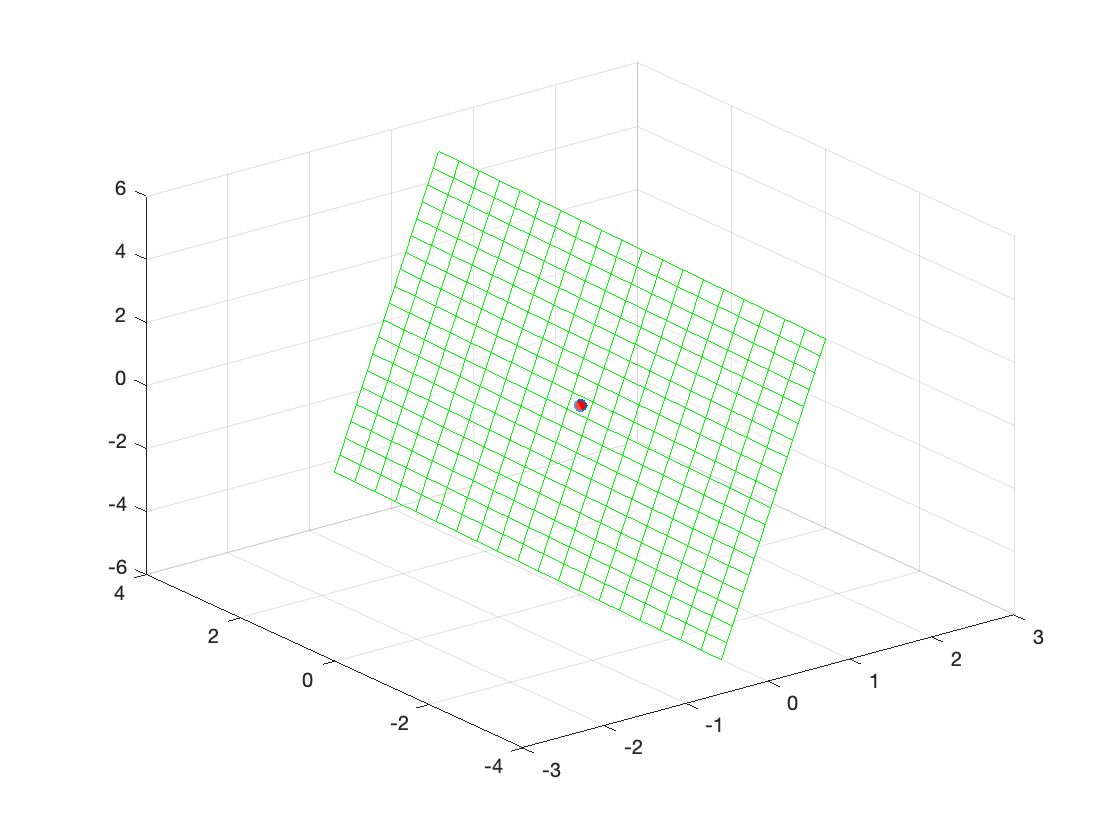

figure
s=linspace(-1.5,1.5,20);
t=linspace(-1.5,1.5,20);
[S,T]=meshgrid(s,t);
X=S-T;
Y=S+T;
Z=2*S+2*T;
mesh(X,Y,Z,'EdgeColor','g','FaceAlpha',0.3)
hold on
plot3(0,0,0,'o','MarkerFaceColor','r')
hold off

Now, the $\text{span}(S)$ is defined as all linear combinations of the vectors in $S$. Do all linear combinations of our two vectors lie in this plane? We know we can write a linear combination of vectors as a matrix times a vector. For example,


$$1\pmatrix{1\cr 1\cr 2}+(-1)\pmatrix{-1\cr 1\cr 2}=\pmatrix{1 & -1\cr 1 & 1\cr 2 & 2}\pmatrix{1\cr -1}$$


Let's check this with Matlab.

u=[1;1;2]; v=[-1;1;2]; 1*u+(-1)*v

ans =      2
     0
     0


Now, let's enter our vectors as columns of a matrix and our constants as a vector.

A=[u,v]

A =      1    -1
     1     1
     2     2


That looks correct.

x=[1;-1]

x =      1
    -1


That also looks correct. Now, what is A*x?

A*x

ans =      2
     0
     0


That's the same as our linear combination above. Now, what's a cool way to take a lot of linear combinations of two vectors in Matlab. We know that 


$$AB=A[\vec b_1,\vec b_2,\ldots,\vec b_p]=[A\vec b_1, A\vec b_1,\ldots,A \vec b_p]$$


so to perform the multiplication, we multiply the leading matrix (which contains the vectors in $S$) times each column of the second matrix.


$$\pmatrix{1 & -1\cr 1 & 1\cr 2 & 2}\pmatrix{1 & -1\cr 1 & 1}=\left[\matrix{\pmatrix{1 & -1\cr 1 & 1\cr 2 & 2}\pmatrix{1\cr -1} & \pmatrix{1 & -1\cr 1 & 1\cr 2 & 2}\pmatrix{1\cr 1}}\right]$$


So this means that we get two linear combinations of our vectors in $S$. Now, Matlab's rand(m,n) will create an $m\times n$ matrix filled with random numbers between 0 and 1. Here is an example. *Note: I am using the rng(n) command to set the same starting point for purpose of this explanation. We don't need to do this if we don't mind getting different random numbers every time we run our code.*

rng(1)
rand(2,6)

ans =     0.4170    0.0001    0.1468    0.1863    0.3968    0.4192
    0.7203    0.3023    0.0923    0.3456    0.5388    0.6852


If we multiply this by 2, the numbers will be between 0 and 2.

rng(1)
2*rand(2,6)

ans =     0.8340    0.0002    0.2935    0.3725    0.7935    0.8384
    1.4406    0.6047    0.1847    0.6911    1.0776    1.3704


And if we subtract 1, we get numbers between -1 and 1, which we save in the variable V.

rng(1)
V=2*rand(2,6)-1

V =    -0.1660   -0.9998   -0.7065   -0.6275   -0.2065   -0.1616
    0.4406   -0.3953   -0.8153   -0.3089    0.0776    0.3704


Now, according to what we explained above, if we multiply A*V, we will get six linear combinations of our two vectors which are the columns of our matrix A.

vecs=A*V

vecs =    -0.6066   -0.6044    0.1088   -0.3186   -0.2841   -0.5320
    0.2747   -1.3951   -1.5218   -0.9364   -0.1288    0.2088
    0.5494   -2.7902   -3.0436   -1.8727   -0.2577    0.4177


Now, let's add each of these vectors to our image above. 

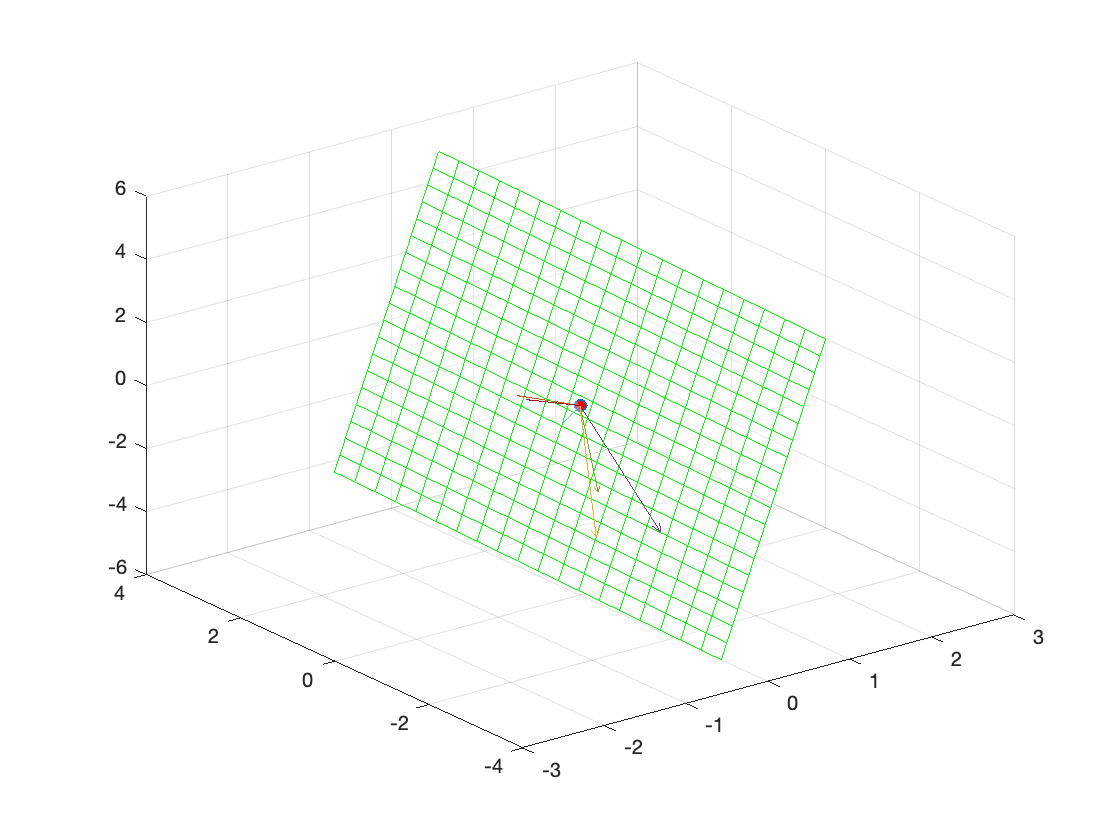

figure
s=linspace(-1.5,1.5,20);
t=linspace(-1.5,1.5,20);
[S,T]=meshgrid(s,t);
X=S-T;
Y=S+T;
Z=2*S+2*T;
mesh(X,Y,Z,'EdgeColor','g','FaceAlpha',0.3)
hold on
plot3(0,0,0,'o','MarkerFaceColor','r')
u=[1;1;2]; v=[-1;1;2];
A=[u,v];
rng(1);
V=2*rand(2,6)-1;
vecs=A*V;
for k=1:6
    quiver3(0,0,0,vecs(1,k),vecs(2,k),vecs(3,k),0)
end
hold off

If you don't trust that they all lie in the plane, rotate the plane to be sure. Now, let's plot 100 linear combinations.

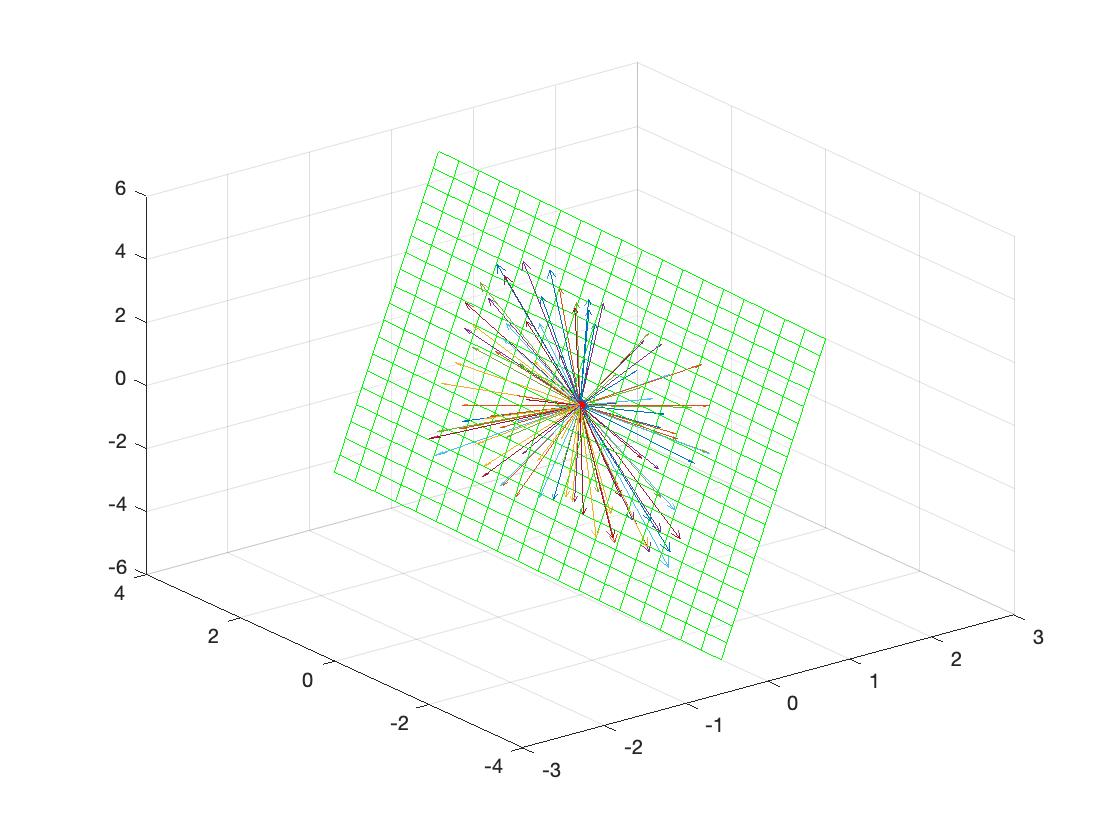

figure
s=linspace(-1.5,1.5,20);
t=linspace(-1.5,1.5,20);
[S,T]=meshgrid(s,t);
X=S-T;
Y=S+T;
Z=2*S+2*T;
mesh(X,Y,Z,'EdgeColor','g','FaceAlpha',0.3)
hold on
plot3(0,0,0,'o','MarkerFaceColor','r')
u=[1;1;2]; v=[-1;1;2];
A=[u,v];
rng(1);
V=2*rand(2,100)-1;
vecs=A*V;
for k=1:100
    quiver3(0,0,0,vecs(1,k),vecs(2,k),vecs(3,k),0)
end
hold off

They all lie in the plane. This is pretty clear evidence that our plane we have drawn is the $\text{span}(S)$.

# Example #3

Let


$$S=\left\{\pmatrix{2\cr 0\cr 1},\ \pmatrix{1\cr 1\cr 0},\ \pmatrix{3\cr1\cr1}\right\}$$


Show that $\text{span}(S)\ne R^3$.

**Solution:** In order that $\text{span}(S)=R^3$, each vector $(a,b,c)^T$ in $R^3$ must be able to be written as a linear combination of our vectors in $S$. Let's see if that is possible.


$$\begin{array}{rcl}
c_1\pmatrix{2\cr 0\cr 1}+c_2\pmatrix{1\cr 1\cr 0}+c_3\pmatrix{3\cr 1\cr 1}&=&\pmatrix{a\cr b\cr c}\\
\pmatrix{2 & 1 & 3\cr 0 & 1 & 1\cr 1 & 0 & 1}\pmatrix{c_1\cr c_2\cr c_3}&=&\pmatrix{a\cr b\cr c}
\end{array}$$


Let's set up the augmented matrix for this system and row reduce.


$$\pmatrix{2 & 1 & 3 & a\cr 0 & 1 & 1 & b\cr 1 & 0 & 1 & c}\ \matrix{R_1\leftrightarrow R_3\cr ~\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 1 & c\cr 0 & 1 & 1 & b\cr 2 & 1 & 3 & a}$$


We can check this with Matlab.

syms a b c
M=[2 1 3 a;0 1 1 b;1 0 1 c];
r1=M(1,:);
r2=M(2,:);
r3=M(3,:);
M=[r3;r2;r1]

$$M = \left(\begin{array}{cccc} 1 & 0 & 1 & c\\ 0 & 1 & 1 & b\\ 2 & 1 & 3 & a \end{array}\right)$$

Same answer. Next,


$$\pmatrix{1 & 0 & 1 & c\cr 0 & 1 & 1 & b\cr 2 & 1 & 3 & a}\ \matrix{~\cr ~\cr R_3-2R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 1 & c\cr 0 & 1 & 1 & b\cr 0 & 1 & 1 & a-2c}$$


We can check this with Matlab.

r1=M(1,:);
r2=M(2,:);
r3=M(3,:);
M=[r1;r2;r3-2*r1]

$$M = \left(\begin{array}{cccc} 1 & 0 & 1 & c\\ 0 & 1 & 1 & b\\ 0 & 1 & 1 & a-2\,c \end{array}\right)$$

Same answer. Next,


$$\pmatrix{1 & 0 & 1 & c\cr 0 & 1 & 1 & b\cr 0 & 1 & 1 & a-2c}\ \matrix{~\cr ~\cr R_3-R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 1 & c\cr 0 & 1 & 1 & b\cr 0 & 0 & 0 & a-b-2c}$$


We can check this with Matlab.

r1=M(1,:);
r2=M(2,:);
r3=M(3,:);
M=[r1;r2;r3-r2]

$$M = \left(\begin{array}{cccc} 1 & 0 & 1 & c\\ 0 & 1 & 1 & b\\ 0 & 0 & 0 & a-b-2\,c \end{array}\right)$$

Same answer. Note that the last row is 


$$0c_1+0c_2+0c_3=a-b-2c$$


Therefore, this system will have answers only if $a-b-2c=0$. Therefore, our vector $(a,b,c)^T$ can be written as a linear combination of the vectors in $S$ if and only if it lies on the plane $a-b-2c=0$. So the $\text{span}(S)$ is the plane $a-b-2c=0$. Can we show that this is true? If $a-b-2c=0$, we can write:


$$\pmatrix{a\cr b\cr c}=\pmatrix{b+2c\cr b\cr c}=\pmatrix{b\cr b\cr 0}+\pmatrix{2c\cr 0\cr c}=b\pmatrix{1\cr 1\cr 0}+c\pmatrix{2\cr 0\cr 1}$$


Let's sketch our plane.

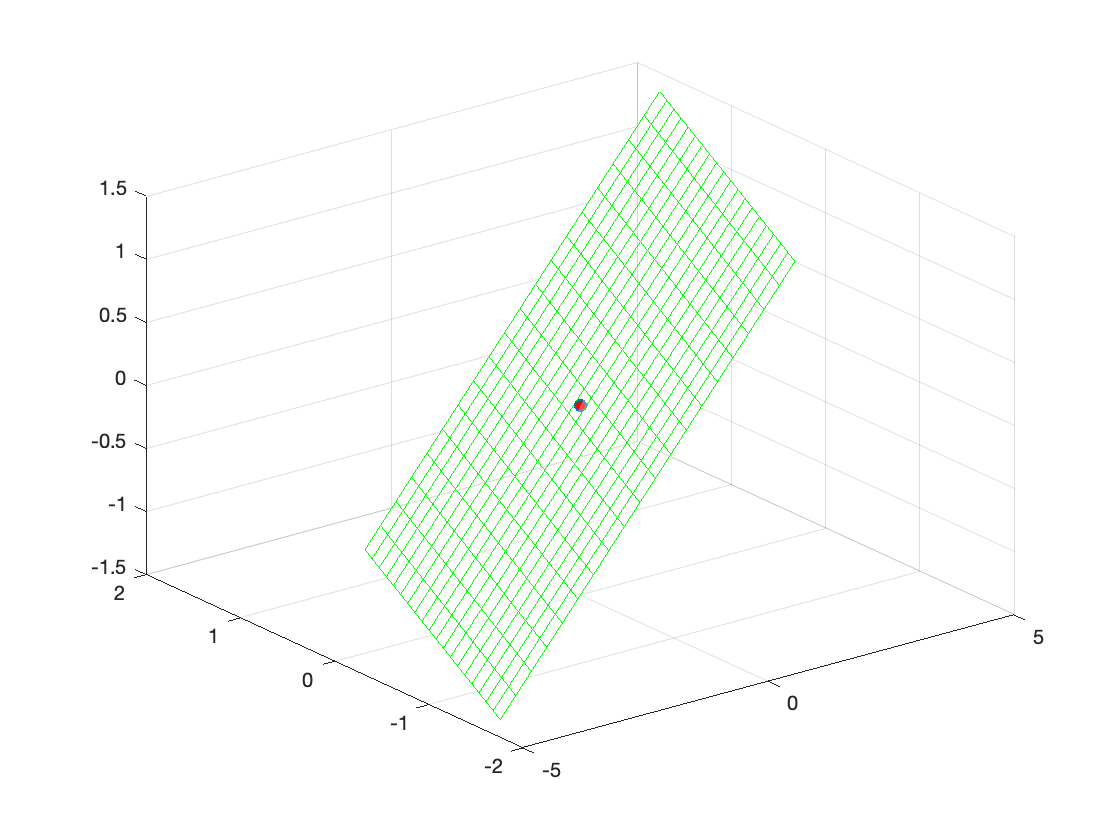

figure
b=linspace(-1.5,1.5,20);
c=linspace(-1.5,1.5,20);
[B,C]=meshgrid(b,c);
X=B+2*C;
Y=B;
Z=C;
mesh(X,Y,Z,'EdgeColor','g','FaceAlpha',0.3)
hold on
plot3(0,0,0,'o','MarkerFaceColor','r')
hold off

Now, we have claimed that this plane is the span of our set $S$, which means that any linear combination of the vectors in $S$ will lie in this plane. Let's use the same trick we used in Example #2 to sketch a whole bunch of linear combinations of the vectors in $S$ and see if they all lie in this plane. This time our matrix $A$ has three columns, so our random numbers must have three rows.

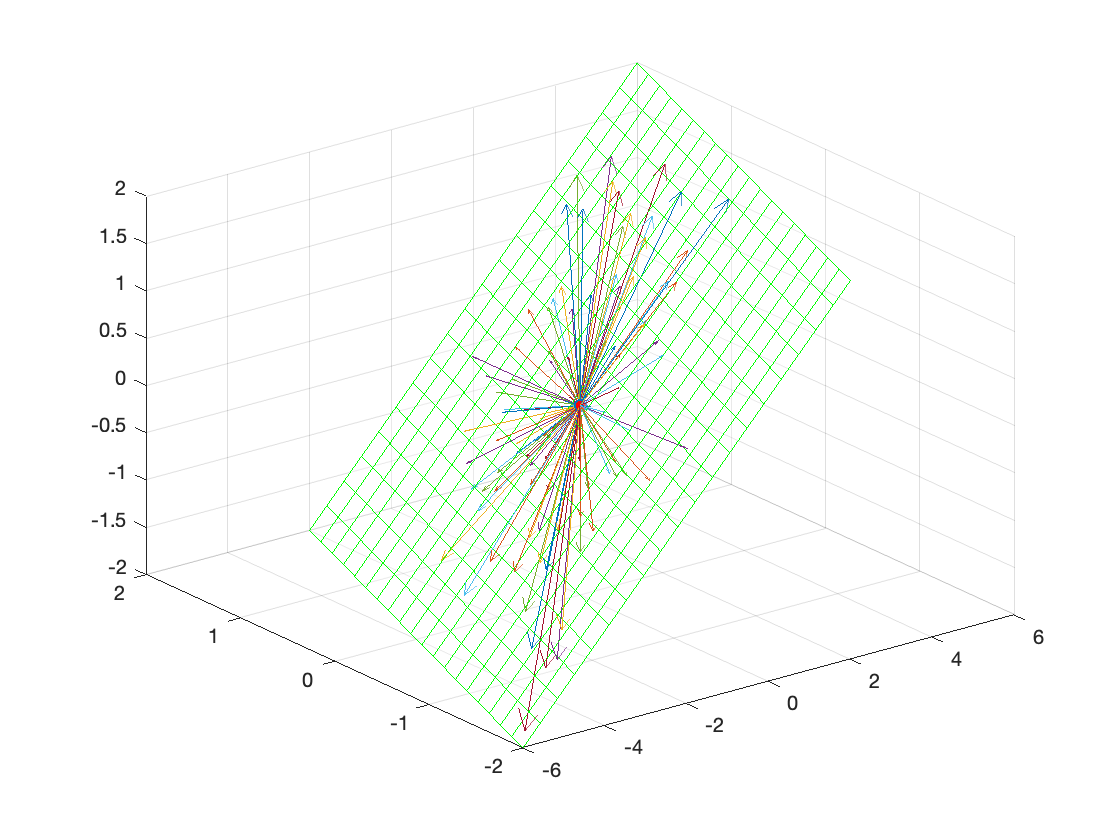

figure
b=linspace(-2,2,20);
c=linspace(-2,2,20);
[B,C]=meshgrid(b,c);
X=B+2*C;
Y=B;
Z=C;
mesh(X,Y,Z,'EdgeColor','g','FaceAlpha',0.3)
hold on
plot3(0,0,0,'o','MarkerFaceColor','r')
u=[2;0;1]; v=[1;1;0]; w=[3;1;1];
A=[u,v,w];
rng(1);
V=2*rand(3,100)-1;
vecs=A*V;
for k=1:100
    quiver3(0,0,0,vecs(1,k),vecs(2,k),vecs(3,k),0)
end
hold off

If you are not sure they all lie in the plane, rotate the plane until you are sure. 

**Question: **Were our vectors in $S$ linearly independent? Let's calculate the determinant of matrix A using Matlab.

det(A)

ans = 0

The determinant is zero, so the vectors 


$$\pmatrix{2\cr 0\cr 1},\qquad \pmatrix{1\cr 1\cr 0},\qquad\text{and}\qquad \pmatrix{3\cr 1\cr 1}$$


are linearly dependent. Note that the third vector is the sum of the first two vectors.

# Example #4

Let


$$S=\left\{\pmatrix{1\cr 0\cr 1},\ \pmatrix{1\cr 1\cr 0},\ \pmatrix{0\cr 1\cr 1}\right\}$$


What is $\text{span}(S)$?

**Solution:** Does this set of vectors span all of $R^3$? As above, let's solve the system


$$\pmatrix{1 & 1 & 0 & a\cr 0 & 1 & 1 & b\cr 1 & 0 & 1 & c}\ \matrix{~\cr ~\cr R_3-R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 0 & a\cr 0 & 1 & 1 & b\cr 0 & -1 & 1 & c-a}$$


We can check this with Matlab.

syms a b c
M=[1 1 0 a;0 1 1 b;1 0 1 c];
r1=M(1,:);
r2=M(2,:);
r3=M(3,:);
M=[r1;r2;r3-r1]

$$M = \left(\begin{array}{cccc} 1 & 1 & 0 & a\\ 0 & 1 & 1 & b\\ 0 & -1 & 1 & c-a \end{array}\right)$$

Same answer. Next,


$$\pmatrix{1 & 1 & 0 & a\cr 0 & 1 & 1 & b\cr 0 & -1 & 1 & c-a}\ \matrix{~\cr ~\cr R_3+R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 0 & a\cr 0 & 1 & 1 & b\cr 0 & 0 & 2 & c+b-a}$$


We can check this with Matlab.

r1=M(1,:);
r2=M(2,:);
r3=M(3,:);
M=[r1;r2;r3+r2]

$$M = \left(\begin{array}{cccc} 1 & 1 & 0 & a\\ 0 & 1 & 1 & b\\ 0 & 0 & 2 & b-a+c \end{array}\right)$$

Same answer. Note that we have a pivot in each of the first three columns, so it doesn't matter what $a$, $b$, and $c$ are, the system has a solution. This means that all vectors $(a,b,c)^T\in R^3$ can be written as a linear combination of the vectors in $S$. This means that $\text{span}(S)=R^3$. Can we visualize this? The answer is "Yes".

This time, we will draw no plane, but we will draw 100 linear combinations of the vectors in $S$.

u=[1;0;1]; v=[1;1;0]; w=[0;1;1]; A=[u,v,w]

A =      1     1     0
     0     1     1
     1     0     1


Note that the columns of A are the vectors of $S$. Now we will generate a $3\times 100$ matrix of random numbers between -1 and 1, and multiply it by A to produce 100 linear combinations of the columns of A.

V=2*rand(3,100)-1;
vecs=A*V;

Now we will plot all of these vectors.

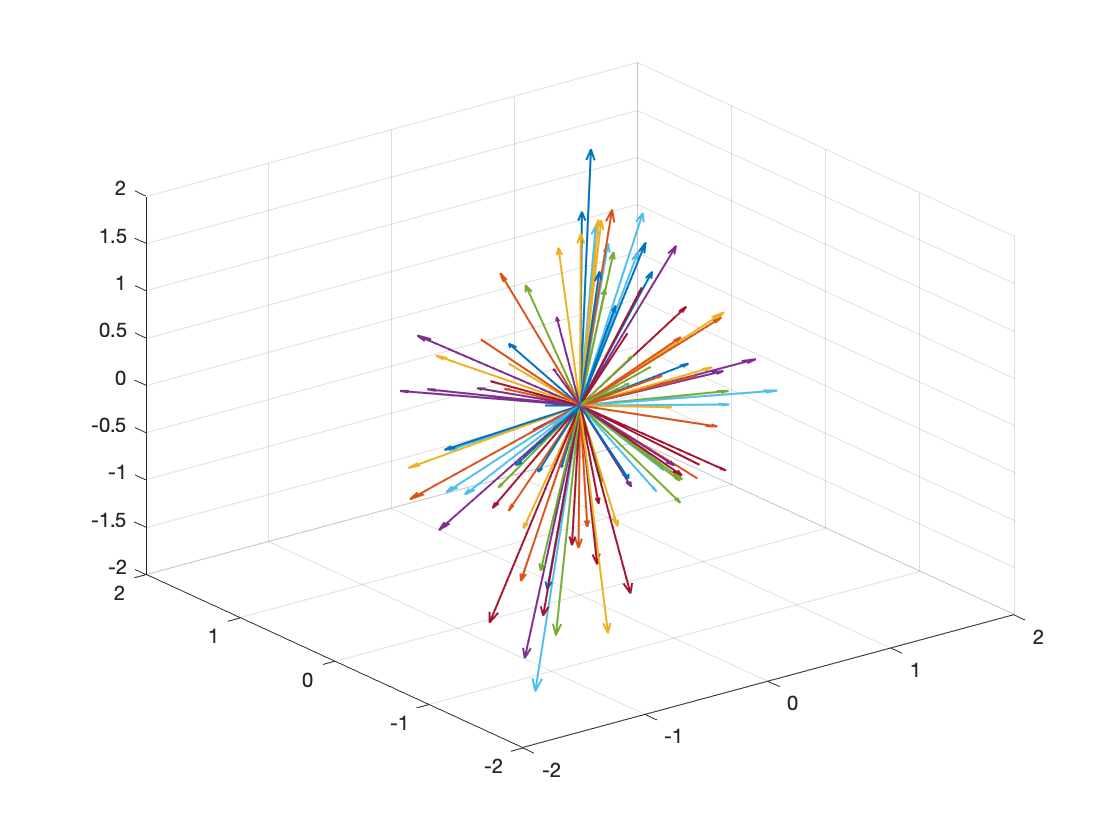

figure
hold on
for k=1:100
    quiver3(0,0,0,vecs(1,k),vecs(2,k),vecs(3,k),0,'LineWidth',1)
end
grid on
view(3)
hold off

Each vector in this image is a linear combination of our vectors in $S$. You can rotate this image to assure yourself that this time they don't lie in a plane. Indeed, they are all over the place, spanning $R^3$.

**Question: **Are the vectors in $S$ linearly independent? Let's use Matlab to find the determinant.

det(A)

ans = 2

The determinant is nonzero, so the three vectors in our set $S$ are linearly independent.